clear all; close all;

## Altitudes

h1 = linspace(    0,  11100, 10); % Troposphere
h2 = linspace(11100,  20000, 10); % Tropopause
h3 = linspace(20000,  32000, 10); % Stratosphere-1
h4 = linspace(32000,  47000, 10); % Stratosphere-2
h5 = linspace(47000,  51000, 10); % Stratopause
h6 = linspace(51000,  71000, 10); % Mesosphere-1
h7 = linspace(71000,  84852, 10); % Mesosphere-2


h = [h1, h2(2:end), h3(2:end), h4(2:end), ...
    h5(2:end), h6(2:end), h7(2:end)];

T = zeros(1,length(h)); % preallocate
a = T; P = T; rho = T;

for i=1:length(h)
    h_ = h(i);
    [T_, a_, P_, rho_] = atmoscoesa(h_);
    T(i)=T_; a(i)=a_; P(i)=P_; rho(i)=rho_;
end

## Plots

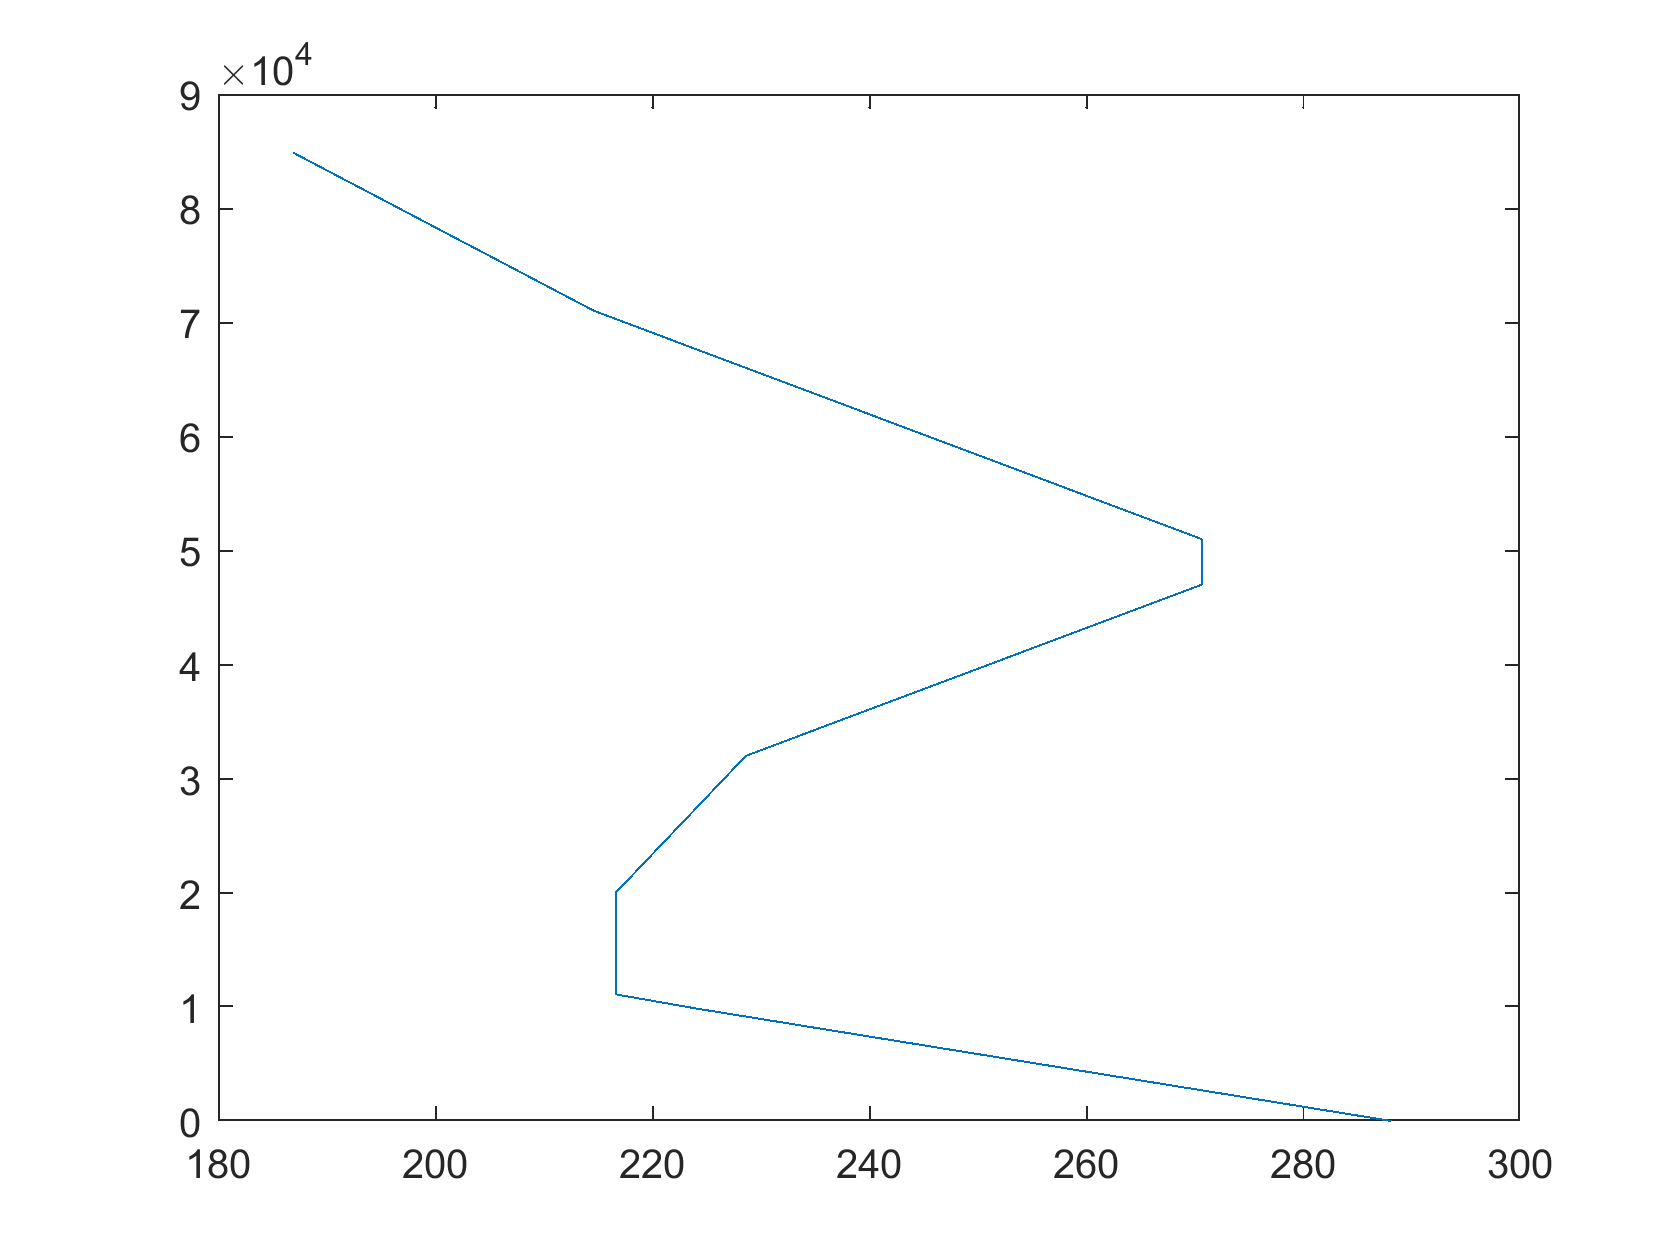

figure(1)
plot(T,h)

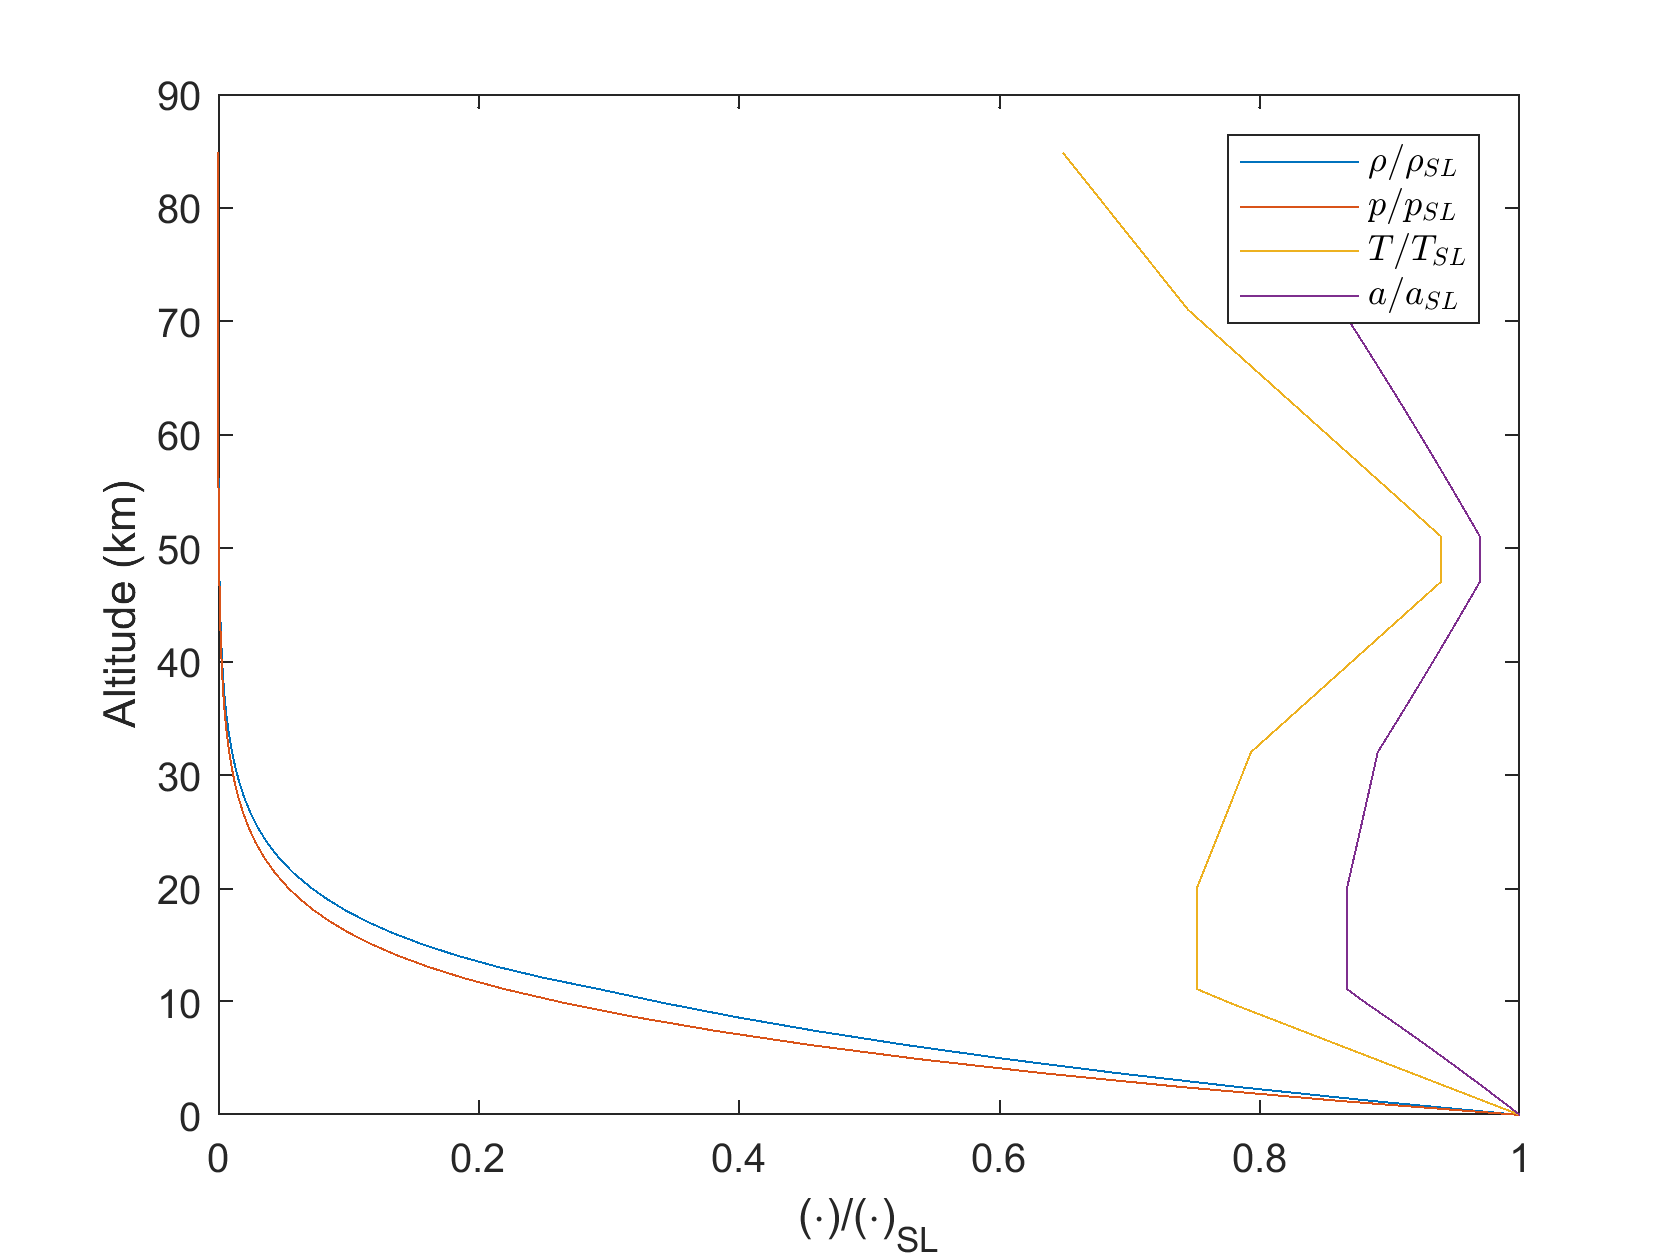


figure(2)
plot(rho./rho(1), h./1000, ...
    P./P(1), h./1000, ...
    T./T(1), h./1000, ...
    a./a(1), h./1000)
xlabel('(\cdot)/(\cdot)_{SL}')
ylabel('Altitude (km)')
lgd = legend('$\rho/\rho_{SL}$','$p/p_{SL}$','$T/T_{SL}$','$a/a_{SL}$');
lgd.Interpreter = 'latex';